# Exercise 3: Testing and Deployment

## Load Environment Info and Trained Agent

To validate the performance of the trained policy, we want to simulate the greedy policy (without exploration) within the humanoid walker environment. Since the training process can take several hours, a pretrained version of the agent has been provided for you to validate.

Load the environment object.

load("EnvironmentInfo.mat");

Load the pretrained agent.

load("TrainedWalkerAgent.mat","agent");

Open the Simulink model.

open_system("HumanoidWalkerRobot.slx");

## Test Greedy Trained Policy

Run a validation episode with no exploration and save the experience.

agent.UseExplorationPolicy = false;
simOpts = rlSimulationOptions(MaxSteps=(60/0.025),NumSimulations=1);
exp = sim(env,agent,simOpts);

Please note that you can also do simulation/validation within the Reinforcement Learning Designer app.

### Test Exploration Policy

As an added bonus, try enabling exploration and run another validation episode to see if you can notice a difference in the agent's behavior. You can also try modifying the exploration settings of the agent to see how these affect it as well. Does the agent still accomplish the walking task? How does the reward compare for episodes with and without exploration? (Reward values can be found in the `experience` struct).

agent.UseExplorationPolicy = true;
experience = sim(env,agent,simOpts);

## Extract Trained Policy from Agent

After verifying the behavior of the trained policy, we can generate C code to deploy it to an embedded system. First, we need to extract the trained policy from the agent.

Open the **Block Parameters** of the **RL Agent** block and select **Generate greedy policy block**.

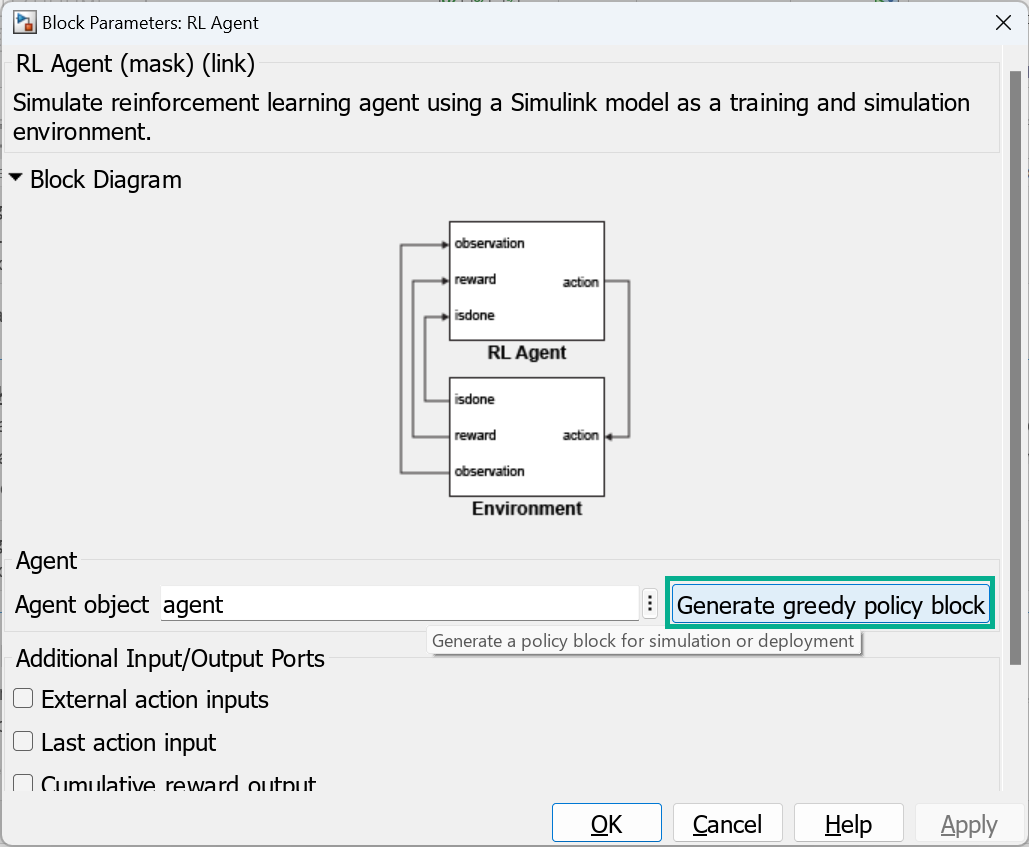

A new Simulink window will open containing a **Policy** block that points to an automatically generated MAT file containing the trained policy information.

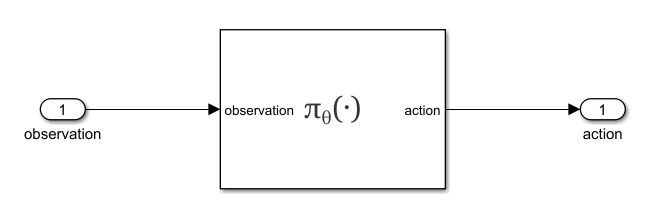

Save this new Simulink model as **TrainedPolicy.slx**. 

## Deploy Trained Policy

Then, navigate to **Apps** > **Embedded Coder**, and in the **C Code** toolbar, select **Build**. 

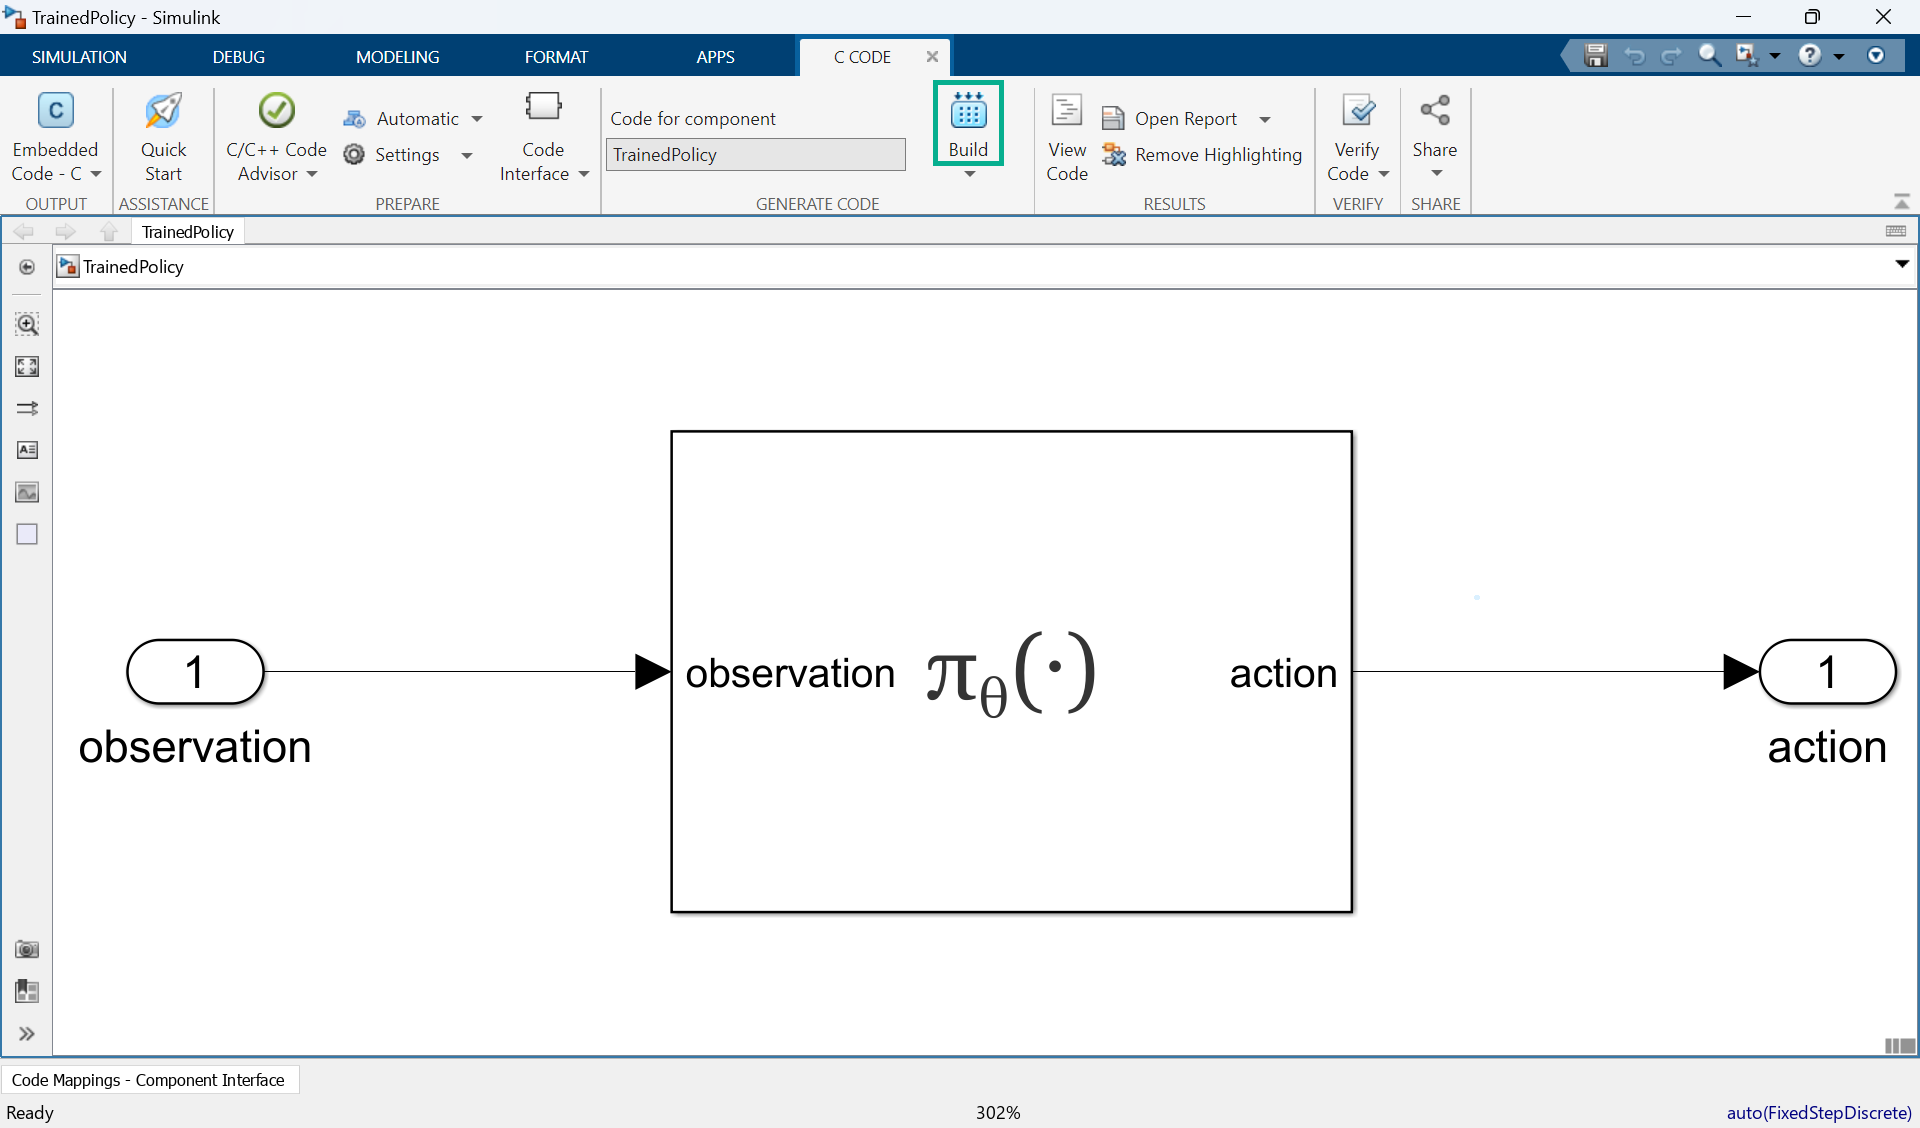

Open the code generation report to view the embedded C code and other code generation information.

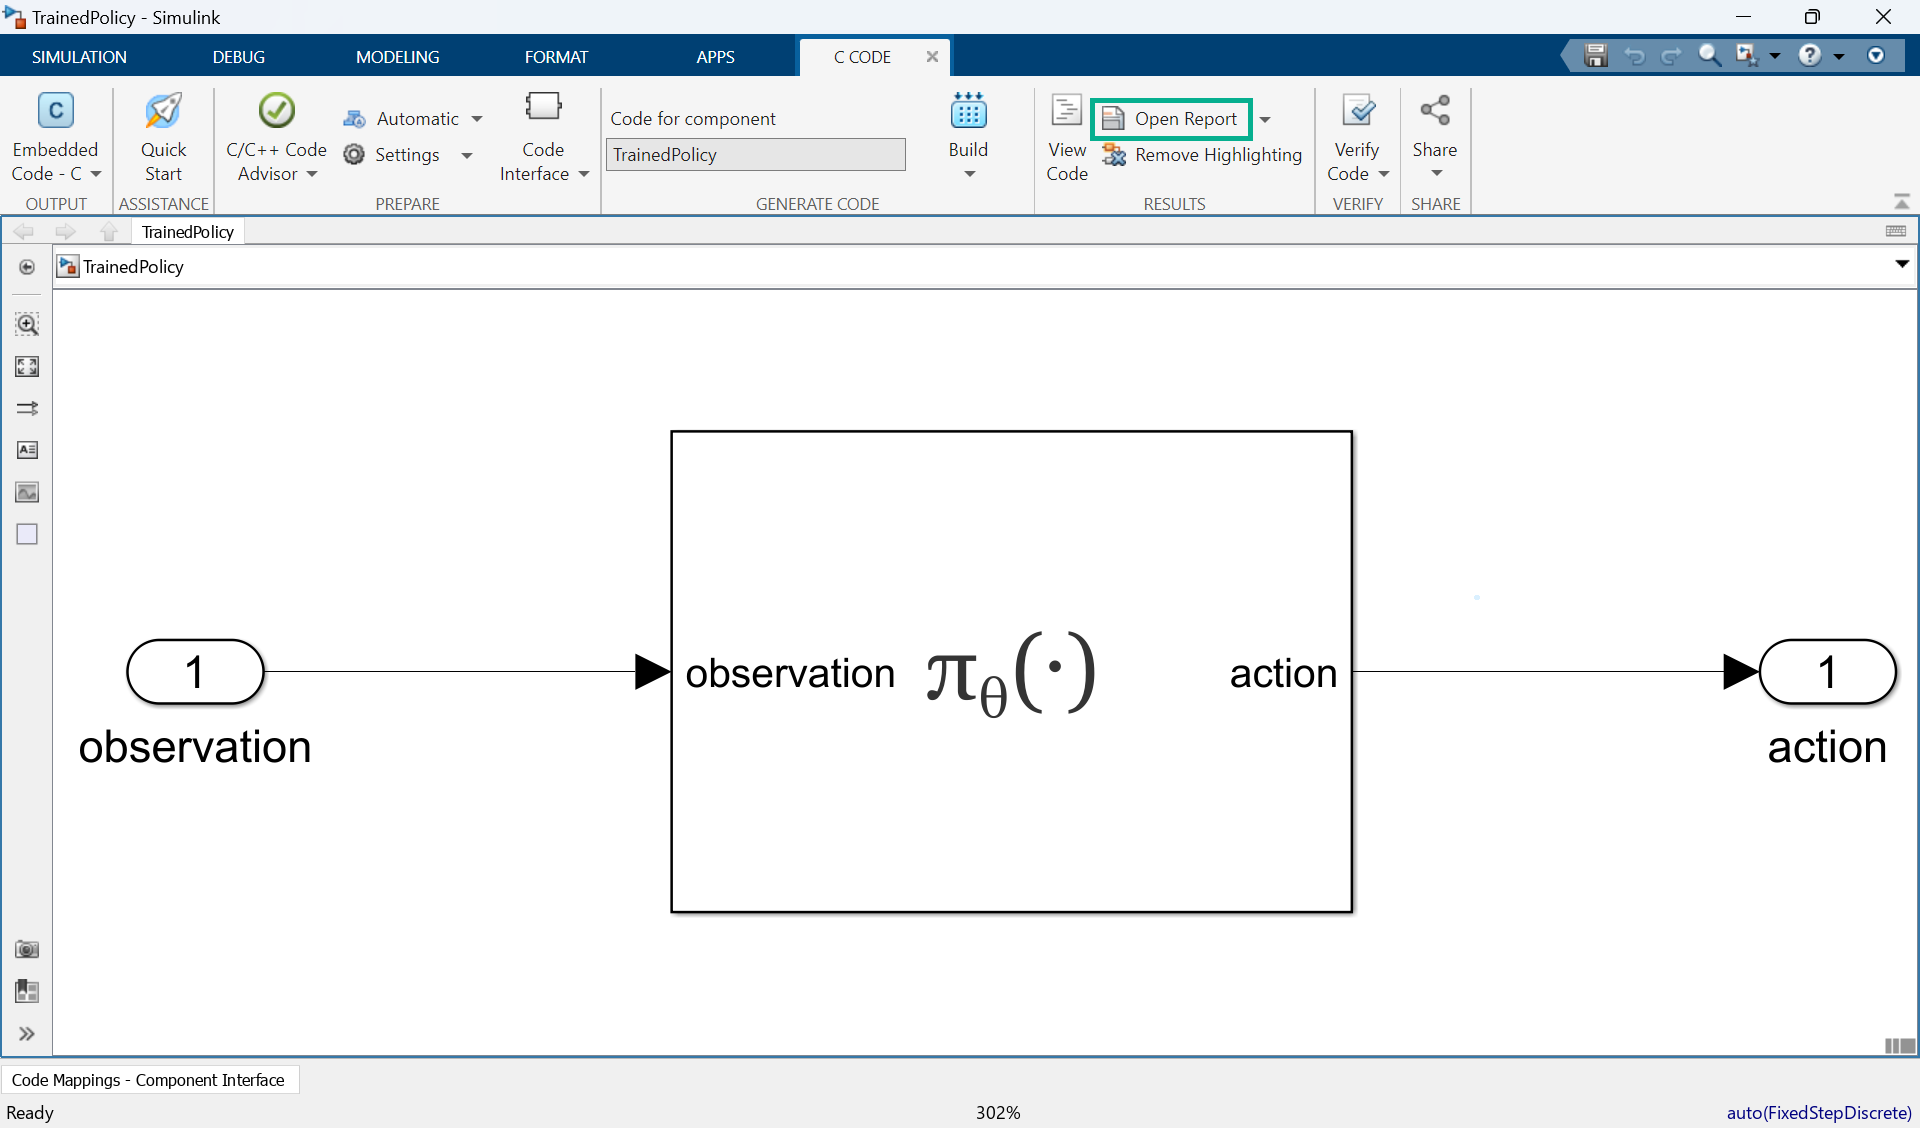

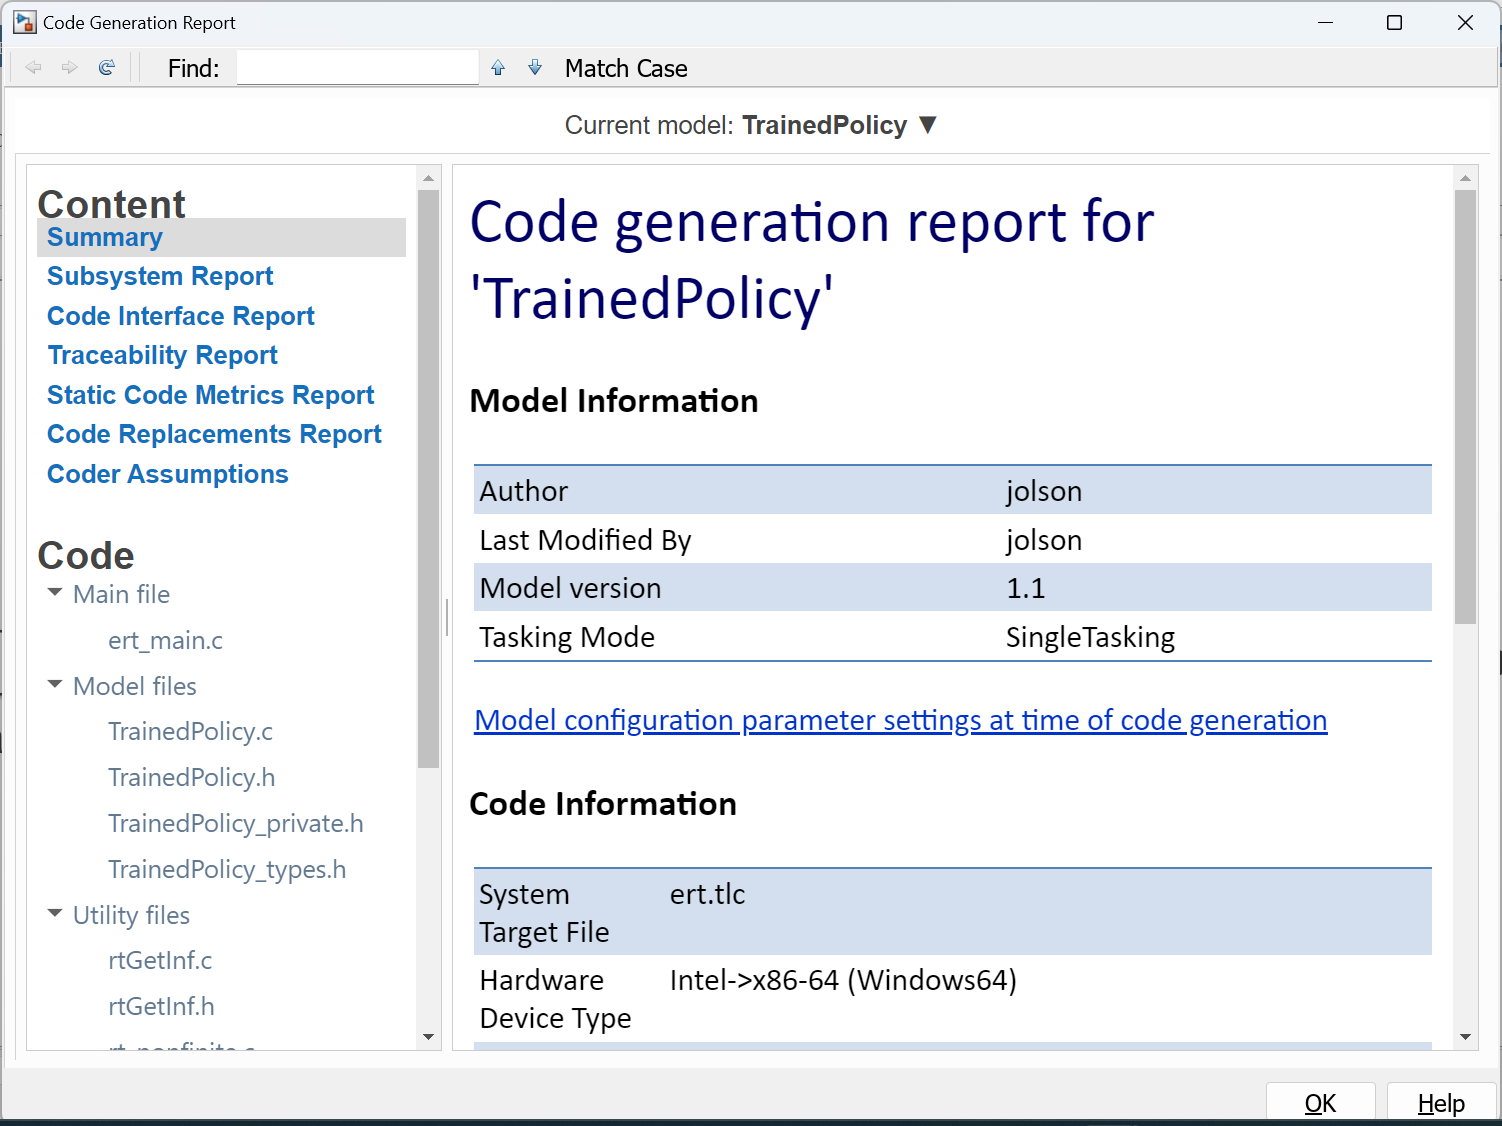

## Bonus Tasks

- Modify some parameters of the robot plant model and see how it affects the performance of the trained policy. Is the policy robust to these changes? How could you account for this during training? (As an example, you can modify the stiffness, damping, or range of motion of the various joints).

- Try modifying the build configuration (build objectives, system target file, etc.) and see if you can notice any difference in the way the embedded C code is generated.

*Copyright 2019-2025 The MathWorks, Inc.*